# Showing the measurements are fluorescence

The excitation light is not a perfect delta function at the peak wavelength.  It falls off with wavelength by several orders of magnitude, but it does not become zero.  There will be some reflected light from the excitation light. The purpose of this notebook is to show that any reflected light will be at a much lower intensity than the raw measurements.  Hence, these measurements are mainly fluorescence and only a small contribution from the reflected light.

This notebook does the analysis for all three excitation lights: 405, 415 and 450 nm lights. All measurements were made  using a PR 670 spectrophotometer. 

### Calibrating the light source SPDs

- We placed a white surface 10 cm from the excitation light (the same distance that was used to illuminate the tongue and lower-lip area)

- The white calibration surface was illuminated by one of three different LED excitation lights.  

- Each light was presented as it presented in the device: through a short wave pass filter with a 450nm cutoff (roll off)

### **Calibrating to estimate the reflected light**

It is conceivable that some of the raw measurements include light that is reflected from the tissue in addition to the fluorescence.  For measurements of tissue fluorescence, reflected light consitutes noise.  These measurements place an upper bound on how much of the raw data could be reflected light.

We will be reporting fluorescence at wavelengths greater than 500 nm.  The LEDs all have a relatively small amount of light in this band, we wanted  (a) to measure the intensity of this light, and (b) to estimate the amount of light that would be reflected (not fluoresced) from the tongue.

The LED light in this range is low, and the spectrophotometer has a limited dynamic range (about 3.5 log units).  We cannot measure both the brightest emission and the very low emissions at off wavelengths.  To calibrate the low light intensity away from the peak we blocked the light at the peak using a 475 nm long pass filter.  This enables the spectrophotometer to use a longer integration time and measure the low intensity light. 

- We illluminated a calibrated white surface with each excitation light and measured the light reflected from the surface using the 475 nm filter

- To calculate the light reflected (not fluoresced) from the tongue, we multiplied this light by the mean of tongue reflectance measurements (obtained from 12 participants).

### **Conclusions**

- The fluorescence signal is much higher than the estimated reflected light.

- There is unwanted thermal energy at wavelengths greater than 680 nm, making those values unreliable. 

## **Initialize**

ieInit;
waves = 380:5:750;
T = oeDatabaseCreate;

## The radiance of the LEDS through the 450nm short pass filter

The light that will arrive at the tongue or lip is from the LED and through the 450 nm short pass filter. We measured intensities for the different LEDs at 1A (max) so to confirm the 'leakage' in the waveband where we are measuring fluorescence.

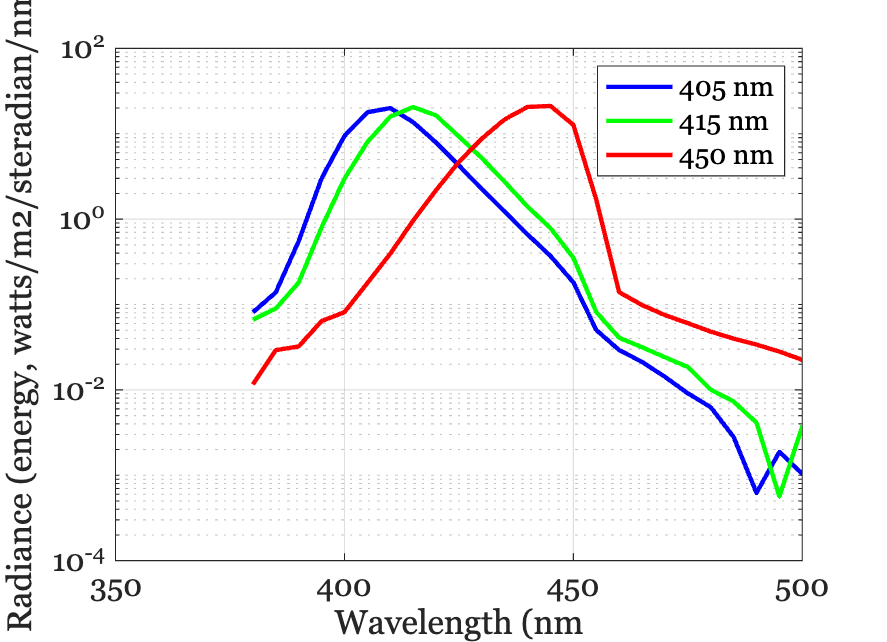

ieNewGraphWin;
lightFiles = {'spd-2024-03-07-Calib-405nm450SPF-1000mA.mat',...
    'spd-2024-03-07-calib-415nm450SPF-1000mA.mat',...
    'spd-2024-03-07-Calib-450nm450SPF-1000mA.mat'};
data(:,1) = ieReadSpectra(lightFiles{1},waves);  
data(:,2) = ieReadSpectra(lightFiles{2},waves);  
data(:,3) = ieReadSpectra(lightFiles{3},waves); 

semilogy(waves,data(:,1),'b',waves,data(:,2),'g',waves,data(:,3),'r','LineWidth',2);
fontsize(gca,14,"pixels");
xlabel('Wavelength (nm');
ylabel('Radiance (energy, watts/m2/steradian/nm)');
xlim([350 500]);
legend('405 nm', '415 nm', '450 nm'); grid on;

- In all three cases the peak is about 10 or 15 nm wide and includes the nominal peak wavelength.

- By 500 nm, where we measure the fluorescence, the light intensity is 3 log units below peak (450nm LED) and 4 log units below peak (405nm and 415 nm LEDs).

- The peak of the 450 LED measurement is a little short of 450nm, presumably because of the filter

- The peak of the 405 nm light is close to 410nm because, well, the world is imperfect

## Reflected light estimates

Not sure we need this graph for anything.

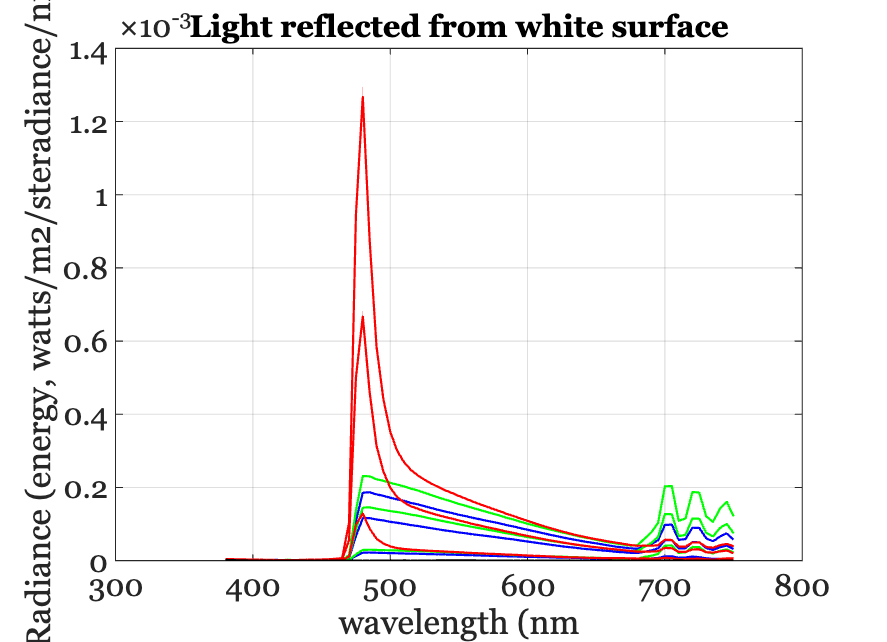

ieNewGraphWin;
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_90mA.mat',waves); plot(waves,data,'b'); hold on;
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_560mA.mat',waves); plot(waves,data,'b');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_980mA.mat',waves); plot(waves,data,'b');

data = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_80mA.mat',waves); plot(waves,data,'g');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_460mA.mat',waves); plot(waves,data,'g'); 
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_910mA.mat',waves); plot(waves,data,'g');

data = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_90mA.mat',waves); plot(waves,data,'r');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_480mA.mat',waves); plot(waves,data,'r');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_870mA.mat',waves); plot(waves,data,'r');
data = ieReadSpectra('spd-2024-03-17-NoiseCheck-completeblack.mat',waves); plot(waves,data,'k');  

title('Light reflected from white surface')
fontsize(gca,14,"pixels"); grid on;
xlabel('wavelength (nm');
ylabel('Radiance (energy, watts/m2/steradiance/nm)');

### Predicted reflectance

To calculate how much light could have been reflected from the tongue, we multiplied the light reflected from white surface with the mean of tongue reflectance measurements.  We had data about tongue reflectance from 12 participants.  Since we did not know the tongue reflectance for each individual, we used this mean for comparison. 

waves = 500:5:780;
tongue = ieReadSpectra('tongue.mat',waves); 
% figure; plot(waves,tongue,'k'); hold on;

meanTongueReflectance = mean(tongue,2);

%{
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_80mA.mat',waves); 
predictedTongueReflectance_415nm_80mA = whiteSurface .* meanTongueReflectance;
whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_460mA.mat',waves); 
predictedTongueReflectance_415nm_460mA = whiteSurface .* meanTongueReflectance;
%}


### Measured radiance and predicted reflectance

Now compare the tongue radiance measurements with predicted tongue reflectance.  

We plot the amount of light we predict to be reflected from the tongue when it was illuminated with the highest intensity light. And we compare it to the light that is measured from the **tongue illuminated with the 415 nm light at 4 different light intensities.**  You can see that the estimated maximum reflected light (when the light was at maximum intensity ) is less than the light measured from the tongue at the lowest intensity.  Thus, we can conclude that at all intensities, the reflected light is noise

### Tongue radiance for 415 nm excitation with long pass at 475

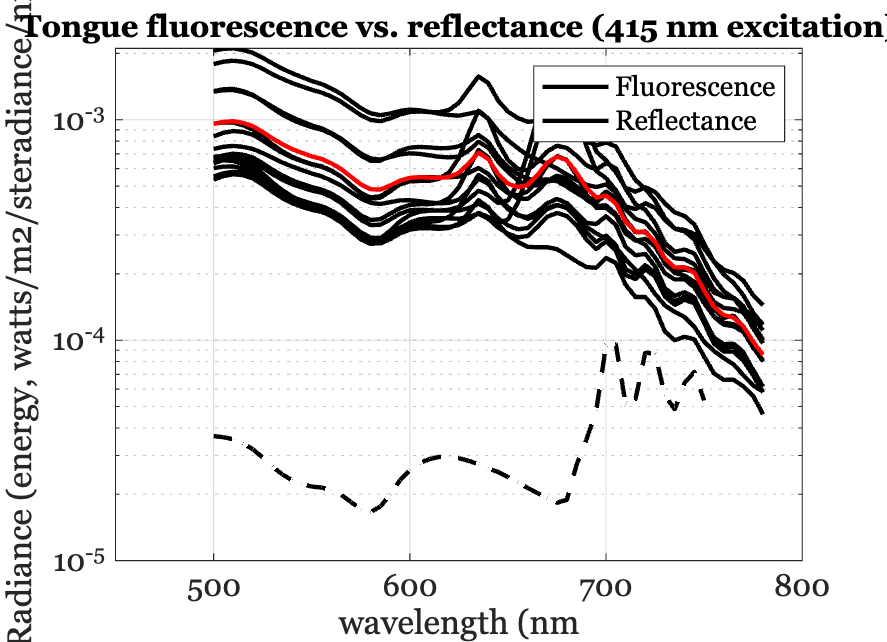

ieNewGraphWin;
dataTable = ieTableGet(T,'substrate','tongue','ewave',415,'elevel',910);

% We might get rid of this or not
%{
 rows = ~strcmp(dataTable.subject,'Jafter');
 dataTable = dataTable(rows,:);
%}

whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-415nm_910mA.mat',waves); 
reflected = whiteSurface .* meanTongueReflectance;

data = zeros(numel(waves),size(dataTable,1));
for ii=1:size(dataTable,1)
    data(:,ii) =ieReadSpectra(dataTable.file(ii),waves);
end
semilogy(waves,data,'k','LineWidth',2); hold on;  
semilogy(waves,reflected,'k--','LineWidth',2); 
semilogy(waves,mean(data,2),'r-','LineWidth',2); hold on;

title ('Tongue fluorescence vs. reflectance (415 nm excitation)');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy, watts/m2/steradiance/nm)');
xlim([450 800]); grid on; legend({'Fluorescence','Reflectance'});

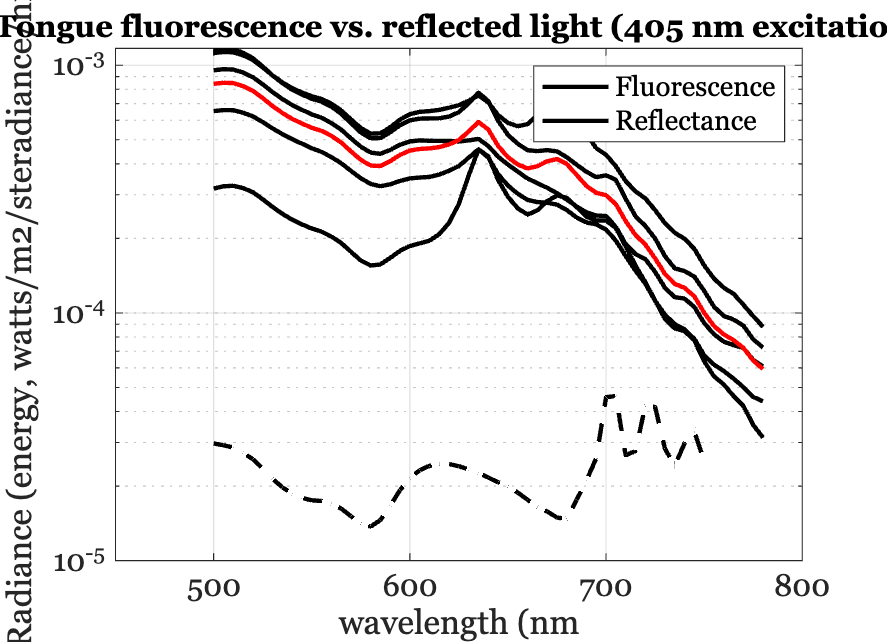

dataTable = ieTableGet(T,'substrate','tongue','ewave',405,'elevel',980);

% We might get rid of this or not
%{
 rows = ~strcmp(dataTable.subject,'Jafter');
 dataTable = dataTable(rows,:);
%}

data = zeros(numel(waves),size(dataTable,1));
for ii=1:size(dataTable,1)
    data(:,ii) =ieReadSpectra(dataTable.file(ii),waves);
end

whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-405nm_980mA.mat',waves); 
reflected = whiteSurface .* meanTongueReflectance;

ieNewGraphWin;
semilogy(waves,data,'k','LineWidth',2); hold on;  
semilogy(waves,reflected,'k--','LineWidth',2); 
semilogy(waves,mean(data,2),'r-','LineWidth',2); hold on;

title ('Tongue fluorescence vs. reflected light (405 nm excitation)');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy, watts/m2/steradiance/nm)');
xlim([450 800]); grid on; legend({'Fluorescence','Reflectance'});

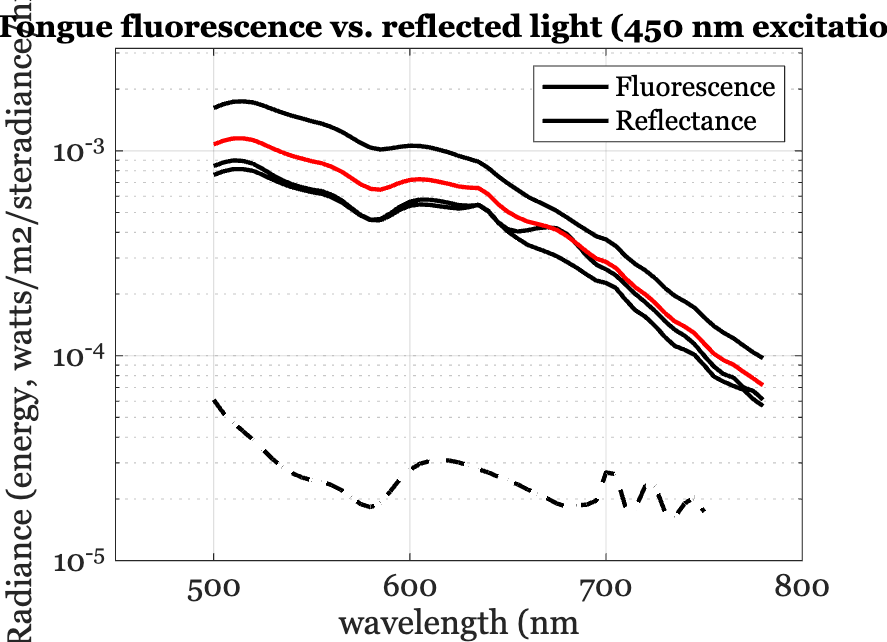

dataTable = ieTableGet(T,'substrate','tongue','ewave',450,'elevel',870);

% We might get rid of this or not
%{
 rows = ~strcmp(dataTable.subject,'Jafter');
 dataTable = dataTable(rows,:);
%}

data = zeros(numel(waves),size(dataTable,1));
for ii=1:size(dataTable,1)
    data(:,ii) =ieReadSpectra(dataTable.file(ii),waves);
end

whiteSurface = ieReadSpectra('spd-2024-03-17-NoiseCheck-450nm_870mA.mat',waves); 
reflected = whiteSurface .* meanTongueReflectance;

ieNewGraphWin;
semilogy(waves,data,'k','LineWidth',2); hold on;  
semilogy(waves,reflected,'k--','LineWidth',2); 
semilogy(waves,mean(data,2),'r-','LineWidth',2); hold on;

title ('Tongue fluorescence vs. reflected light (450 nm excitation)');
fontsize(gca,14,"pixels");
xlabel('wavelength (nm');
ylabel('Radiance (energy, watts/m2/steradiance/nm)');
xlim([450 800]); ylim([10^-5 10^-2.5]);
grid on; legend({'Fluorescence','Reflectance'});

We did not measure reflectance from the lower lip, but we could if we wanted to

We did measure fluorescence from the lower lip area, shown below